**Exercise. **You can write the DC motor angular velocity transfer function as

        
$$\frac{\Omega}{V} = \frac{g}{ s^2 + bs + c}$$


(a) Suppose that a DC motor has constants $g =60$, $b = 2.3$, and $c = 11$. Define the transfer function in MATLAB using the [`tf`](https://www.mathworks.com/help/control/ref/tf.html) function. 

% Write your code here
g = 60; b = 2.3; c=11; 
clear H 
H = tf(g,[1,b,c])

H =
 
         60
  ----------------
  s^2 + 2.3 s + 11
 
Continuous-time transfer function.
Model Properties


(b) Is the system stable? You can plot the poles in the $s$-plane using the [`pzmap`](https://www.mathworks.com/help/control/ref/lti.pzmap.html) function. For example, to plot the poles of a transfer function `G,` use:

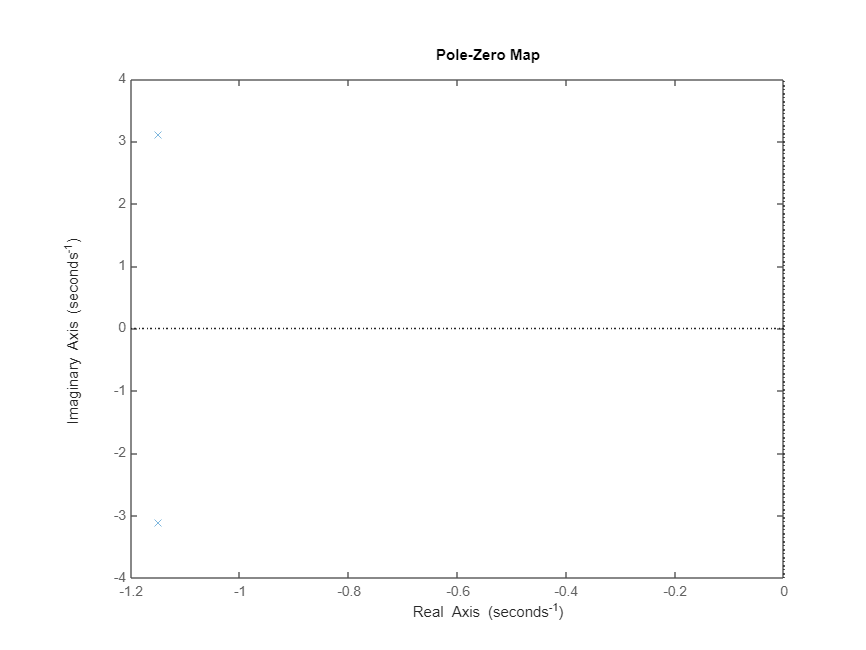

% Write your code here
pzmap(H)

(c) What are the poles of the transfer function? You can use the [`pole`](https://www.mathworks.com/help/control/ref/lti.pole.html) function to compute the poles of a dynamic system in MATLAB. For example, to identify the poles of a transfer function R, use:

% Write your code here
pole(H)

ans =   -1.1500 + 3.1109i
  -1.1500 - 3.1109i


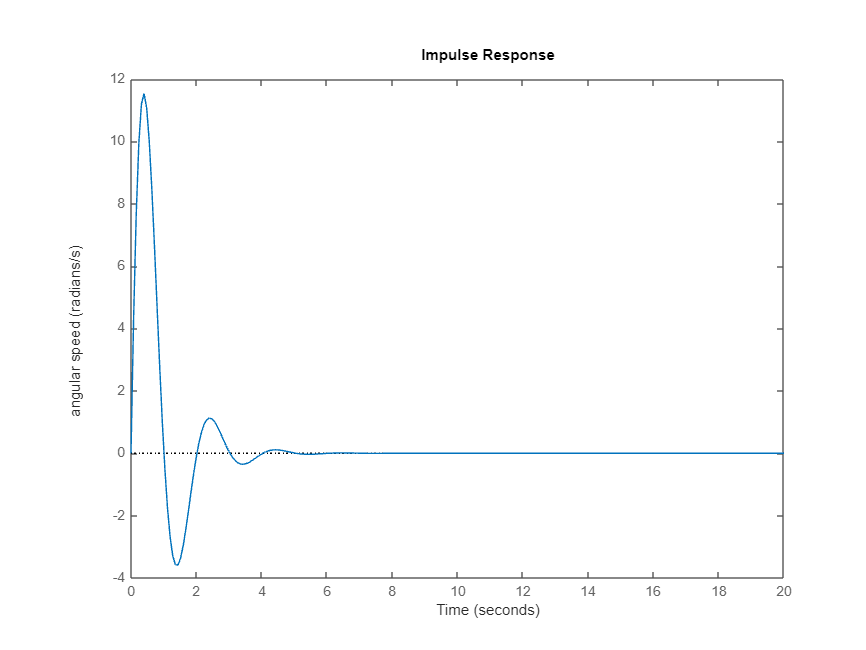

impulse(H,[0,20])
ylabel('angular speed (radians/s)')

**  Reflect.** 

- What response would you expect for a brief (impulse) applied voltage in a physical DC motor?

- Based on the poles identified in this exercise, what impulse response do you expect?

- Does the behavior suggested by the poles match your intuition for a physical DC motor? Does the pole analysis suggest any unexpected behaviors?